%=========================================================================
% Lecture 16: In Class Tutorial
%
% This function calculates the radial equilibrium function for an axially 
% stretched and pressurized thick wall vessel and is part of the set of 
% equations you will implement for your vasculature project
%
% Input data: 
%   luminal pressure (Pi), axial stretch (lambdaz_v) 
%   material parameters, radii in ktf (Ri, Ro)
%
% Output data:
%   approximation of the outer radius, ro
%
% The inverse solution of the radial equilibrium involves finding
% the root of the equation:
%   Pi - int_{ri}^{ro} (tqq-trr)/r dr = 0
%=========================================================================

% Clean environemnts
close all, clear all, clc

Load and Define INPUT DATA


% Control refers to a age-matched healthy model
control_data = load("Input_HypertensionControl_ATA.mat");
test_data = load("Input_Hypertension_ATA.mat");

% Obtains material parameters
material_control = control_data.estimated_parameters;
material_test = test_data.estimated_parameters;

% Loads control parameters
control_lambdaz_exp = control_data.data_kl.lambdaz_exp;
control_Psys_exp = control_data.data_kl.Psys_exp*0.133322; % From mmHg to kPa
control_ref_outer_radius = control_data.data_ktf.or_exp;
control_ref_inner_radius = control_data.data_ktf.ir_exp;
control_thickness = control_data.data_ktf.h_exp;

% Load test parameters (hypertensions)
test_lambdaz_exp = test_data.data_kl.lambdaz_exp;
test_Psys_exp = test_data.data_kl.Psys_exp*0.133322; % From mmHg to kPa
test_ref_outer_radius = test_data.data_ktf.or_exp;
test_ref_inner_radius = test_data.data_ktf.ir_exp;
test_thickness = test_data.data_ktf.h_exp;

%% Solve the equilibrium equation
% Equilibrium equation for a pressurized and axially stretched vessel
% Unknown: outer radius, ro
% ro will be estimated as the roots of the equilibrium equation

H=cell(1,2);
H{1,1}=@equilibrium_r_or_loaded; %handle to equilibrium equation 
H{1,2}=@equilibrum_z_fz_loaded;

% Parameter to be estimated in loaded configuration is the outer radius (ro) 
% x0 is the initial guess for ro based on the input experimental data

% DELIVERABLE - Plot Luminal Pressure vs Outer Diameter

% All luminal presure to be tested
luminalP = 10:5:140;

% Stretches to be modeled
control_axialStretch = [control_lambdaz_exp, control_lambdaz_exp*1.05, control_lambdaz_exp*0.95];
test_axialStretch = [test_lambdaz_exp, test_lambdaz_exp*1.05, test_lambdaz_exp*0.95];

% Initialize radius result
control_or_est = zeros(3, length(luminalP));
test_or_est = zeros(3, length(luminalP));

% Initialize force results
control_fz_est = zeros(3, length(luminalP));
test_fz_est = zeros(3, length(luminalP));


% Loop through stretches
for stretch_index = 1:length(control_axialStretch)
    control_stretch = control_axialStretch(stretch_index)
    test_stretch = test_axialStretch(stretch_index)
    
    % Loop through pressures

    for P_index = 1:length(luminalP)

        % Current pressure being tested
        Pi = luminalP(P_index);
        Pi = Pi*0.133322; % From mmHg to kPa

        % GET R USING NEWTON RAPHSON% 

        % Control
        control_r = Newton_Raphson(H{1,1}, control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch, Pi, material_control, ...
            control_ref_outer_radius); 
        % Save results
        control_or_est(stretch_index, P_index) = control_r;

        % Test
        test_r = Newton_Raphson(H{1,1}, test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, Pi, material_test, ...
            test_ref_outer_radius); 
        % Save results
        test_or_est(stretch_index, P_index) = test_r;


        % GET CURRENT F WITH OPTIMIZED R

        % Control
        control_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch,material_control,control_r);

        % Test
        test_fz_est(stretch_index, P_index) = equilibrium_z_fz_loaded(test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, material_test,test_r);
        
        
    end

end

control_stretch = 1.9761

test_stretch = 1.4955

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.6272

---
Maximum number of iterations reached
---


iter = 1000

f = -1.6431e-14

x = 0.9417

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.6779

---
Maximum number of iterations reached
---


iter = 1000

f = -1.1990e-14

x = 0.9522

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.7501

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9650

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.8349

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 0.9804

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.9095

---
Maximum number of iterations reached
---


iter = 1000

f = -1.3323e-15

x = 0.9976

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9670

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.0159

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 1.0113

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0339

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0463

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.0510

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 1.0748

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0668

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0987

---
Maximum number of iterations reached
---


iter = 1000

f = -7.1054e-15

x = 1.0809

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1191

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.0936

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1368

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1050

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.1524

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1152

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1662

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1244

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1787

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.1327

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1900

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.1403

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2003

---
Maximum number of iterations reached
---


iter = 1000

f = 2.3093e-14

x = 1.1472

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.2097

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1535

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-15

x = 1.2185

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.1593

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2265

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5987e-14

x = 1.1647

---
Maximum number of iterations reached
---


iter = 1000

f = 1.5987e-14

x = 1.2341

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1697

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2411

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1744

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.2477

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.1787

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2540

---
Maximum number of iterations reached
---


iter = 1000

f = 3.1974e-14

x = 1.1828

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2598

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-14

x = 1.1866

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2654

---
Maximum number of iterations reached
---


iter = 1000

f = 3.1974e-14

x = 1.1903

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2706

---
Maximum number of iterations reached
---


iter = 1000

f = 4.6185e-14

x = 1.1937

control_stretch = 2.0749

test_stretch = 1.5703

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4425e-15

x = 0.6145

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 0.9401

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 0.6577

---
Maximum number of iterations reached
---


iter = 1000

f = -1.8874e-14

x = 0.9474

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.7177

---
Maximum number of iterations reached
---


iter = 1000

f = 2.2204e-15

x = 0.9558

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-16

x = 0.7924

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.9654

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-15

x = 0.8661

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-15

x = 0.9763

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9267

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 0.9885

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9743

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0018

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0121

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.0157

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0428

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0299

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0685

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.0438

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.0904

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.0571

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.1093

---
Maximum number of iterations reached
---


iter = 1000

f = -1.0658e-14

x = 1.0695

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1259

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.0810

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1406

---
Maximum number of iterations reached
---


iter = 1000

f = -1.2434e-14

x = 1.0915

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1539

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.1011

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1658

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.1099

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.1767

---
Maximum number of iterations reached
---


iter = 1000

f = 1.9540e-14

x = 1.1179

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1867

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-14

x = 1.1253

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1959

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1321

---
Maximum number of iterations reached
---


iter = 1000

f = -7.1054e-15

x = 1.2044

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.1383

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.2123

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0198e-14

x = 1.1441

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2197

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1495

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-15

x = 1.2267

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.1545

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.2332

---
Maximum number of iterations reached
---


iter = 1000

f = 2.4869e-14

x = 1.1592

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2393

---
Maximum number of iterations reached
---


iter = 1000

f = 3.9080e-14

x = 1.1636

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2452

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1678

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2507

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1717

control_stretch = 1.8773

test_stretch = 1.4207

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-16

x = 0.6396

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 0.9510

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-16

x = 0.6965

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-16

x = 0.9644

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.7784

---
Maximum number of iterations reached
---


iter = 1000

f = -1.3323e-15

x = 0.9814

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.8683

---
Maximum number of iterations reached
---


iter = 1000

f = -2.2204e-15

x = 1.0009

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-16

x = 0.9416

---
Maximum number of iterations reached
---


iter = 1000

f = -4.8850e-15

x = 1.0211

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 0.9963

---
Maximum number of iterations reached
---


iter = 1000

f = -4.4409e-15

x = 1.0405

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0381

---
Maximum number of iterations reached
---


iter = 1000

f = 3.5527e-15

x = 1.0583

---
Maximum number of iterations reached
---


iter = 1000

f = -2.6645e-15

x = 1.0712

---
Maximum number of iterations reached
---


iter = 1000

f = 2.6645e-15

x = 1.0743

---
Maximum number of iterations reached
---


iter = 1000

f = -8.8818e-16

x = 1.0983

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.0884

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1210

---
Maximum number of iterations reached
---


iter = 1000

f = 9.7700e-15

x = 1.1010

---
Maximum number of iterations reached
---


iter = 1000

f = 4.4409e-15

x = 1.1404

---
Maximum number of iterations reached
---


iter = 1000

f = 1.3323e-14

x = 1.1122

---
Maximum number of iterations reached
---


iter = 1000

f = -5.3291e-15

x = 1.1573

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.1222

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.1722

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.1312

---
Maximum number of iterations reached
---


iter = 1000

f = -3.5527e-15

x = 1.1855

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1394

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1974

---
Maximum number of iterations reached
---


iter = 1000

f = -1.7764e-15

x = 1.1468

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.2083

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1535

---
Maximum number of iterations reached
---


iter = 1000

f = 1.7764e-15

x = 1.2182

---
Maximum number of iterations reached
---


iter = 1000

f = 3.0198e-14

x = 1.1597

---
Maximum number of iterations reached
---


iter = 1000

f = 0

x = 1.2273

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1654

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.2357

---
Maximum number of iterations reached
---


iter = 1000

f = 8.8818e-15

x = 1.1707

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.2435

---
Maximum number of iterations reached
---


iter = 1000

f = 4.0856e-14

x = 1.1756

---
Maximum number of iterations reached
---


iter = 1000

f = 1.9540e-14

x = 1.2508

---
Maximum number of iterations reached
---


iter = 1000

f = 2.3093e-14

x = 1.1802

---
Maximum number of iterations reached
---


iter = 1000

f = 1.2434e-14

x = 1.2576

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.1845

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.2639

---
Maximum number of iterations reached
---


iter = 1000

f = 5.3291e-15

x = 1.1885

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.2700

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2633e-14

x = 1.1923

---
Maximum number of iterations reached
---


iter = 1000

f = 1.0658e-14

x = 1.2756

---
Maximum number of iterations reached
---


iter = 1000

f = 7.1054e-15

x = 1.1959

---
Maximum number of iterations reached
---


iter = 1000

f = 1.4211e-14

x = 1.2810

---
Maximum number of iterations reached
---


iter = 1000

f = 4.2633e-14

x = 1.1993

---
Maximum number of iterations reached
---


iter = 1000

f = 2.1316e-14

x = 1.2861

---
Maximum number of iterations reached
---


iter = 1000

f = 2.8422e-14

x = 1.2025

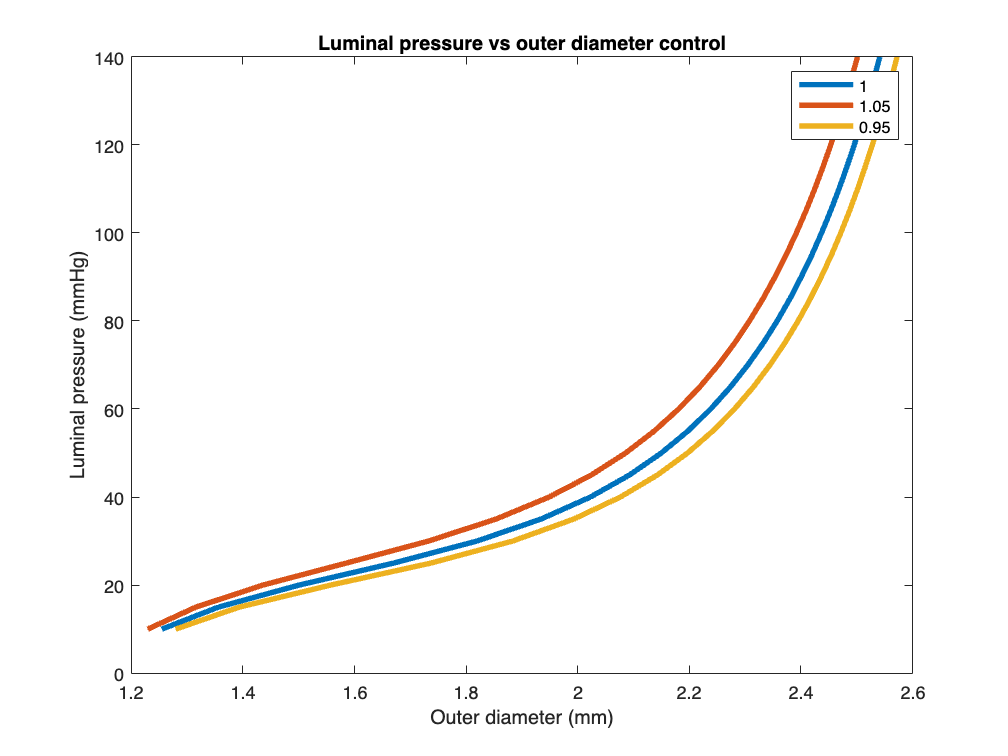

% Find diameter
control_diam = control_or_est .* 2;
test_diam = test_or_est .* 2;

% Plot
figure()
plot(control_diam(1,:),luminalP, control_diam(2,:),luminalP, control_diam(3,:),luminalP, 'LineWidth',3)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure (mmHg)")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter control")

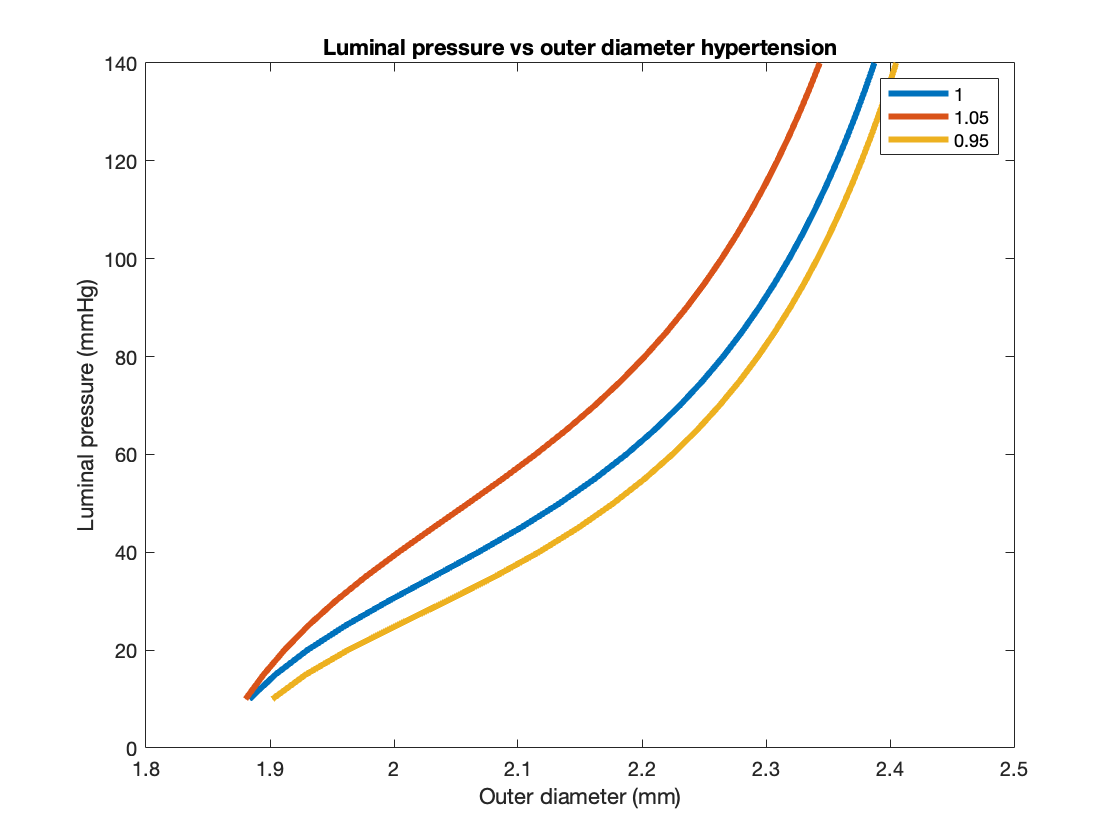


% Plot
figure()
plot(test_diam(1,:),luminalP, test_diam(2,:),luminalP, test_diam(3,:),luminalP, 'LineWidth',3)
xlabel("Outer diameter (mm)")
ylabel("Luminal pressure (mmHg)")
legend("1", "1.05", "0.95")
title("Luminal pressure vs outer diameter hypertension")

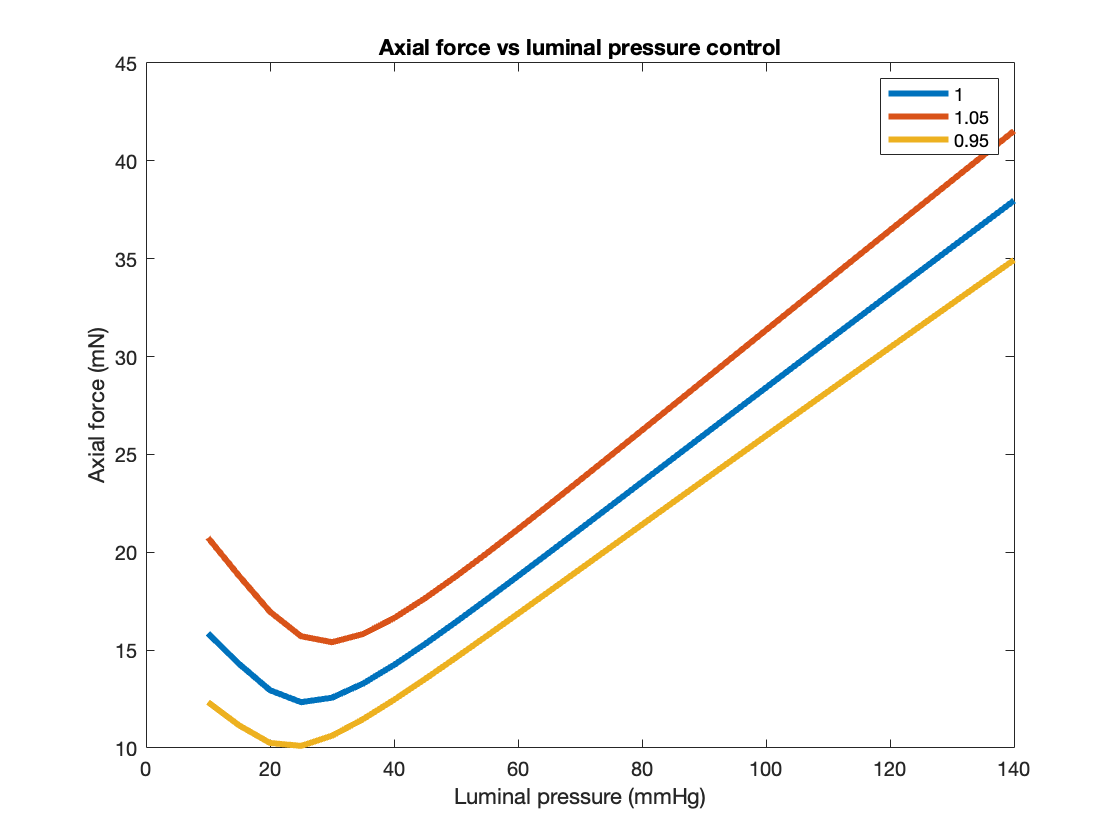


% Plot
figure()
plot(luminalP, control_fz_est(1,:),luminalP, control_fz_est(2,:),luminalP, control_fz_est(3,:), 'LineWidth',3)
xlabel("Luminal pressure (mmHg)")
ylabel("Axial force (mN)")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure control")

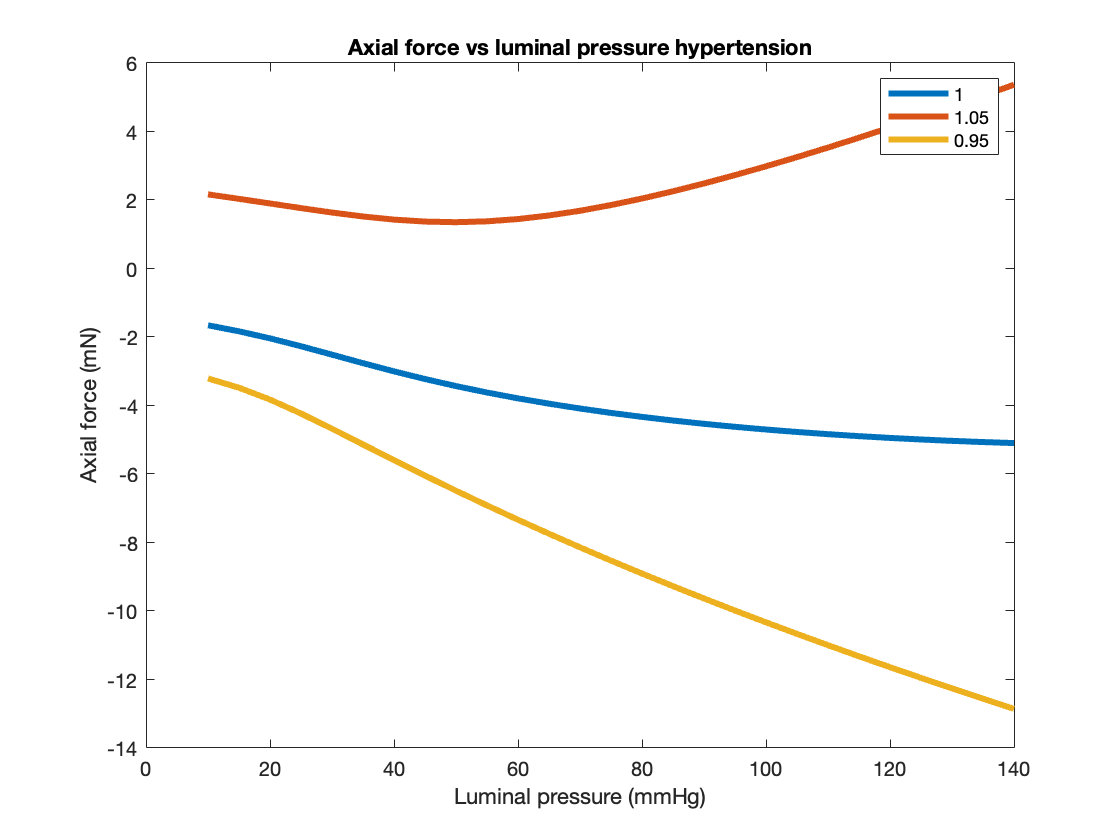


% Plot
figure()
plot(luminalP, test_fz_est(1,:),luminalP, test_fz_est(2,:),luminalP, test_fz_est(3,:), 'LineWidth',3)
xlabel("Luminal pressure (mmHg)")
ylabel("Axial force (mN)")
legend("1", "1.05", "0.95")
title("Axial force vs luminal pressure hypertension")

% DELIVERABLE plot radial, circumferential, axial components of Cauchy Stress vs radial position

% Convert units
control_Psys_exp = control_Psys_exp.* 0.133322;
test_Psys_exp = test_Psys_exp .* 0.133322;

% control
control_r = Newton_Raphson(H{1,1}, control_ref_inner_radius, ...
            control_ref_outer_radius, control_stretch, control_Psys_exp, material_control, ...
            control_ref_outer_radius);

---
Maximum number of iterations reached
---


iter = 1000

f = 5.1625e-15

x = 0.5849

[control_stress_rr, control_stress_theta, control_stress_zz, R_control] = lagrange_stress(control_ref_inner_radius,control_ref_outer_radius,control_axialStretch(1,1),control_Psys_exp,material_control, control_r)

control_stress_rr =   260.6644  261.2592  261.9375  262.6937  263.5234  264.4226  265.3880  266.4169  267.5070  268.6568  269.8648  271.1304  272.4532  273.8333  275.2712  276.7680  278.3250  279.9442  281.6281  283.3797


control_stress_theta =     0.5386   -0.3636   -1.1024   -1.6906   -2.1396   -2.4596   -2.6596   -2.7476   -2.7309   -2.6158   -2.4078   -2.1122   -1.7332   -1.2748   -0.7404   -0.1330    0.5450    1.2913    2.1043    2.9825


control_stress_zz =    -0.2594    0.1443    0.5699    1.0184    1.4910    1.9888    2.5131    3.0653    3.6470    4.2599    4.9058    5.5868    6.3050    7.0629    7.8632    8.7089    9.6033   10.5501   11.5534   12.6178


R_control =     0.5200    0.5169    0.5137    0.5105    0.5073    0.5039    0.5005    0.4971    0.4936    0.4900    0.4863    0.4826    0.4788    0.4749    0.4710    0.4670    0.4629    0.4587    0.4544    0.4501



% test
test_r = Newton_Raphson(H{1,1}, test_ref_inner_radius, ...
            test_ref_outer_radius, test_stretch, test_Psys_exp, material_test, ...
            test_ref_outer_radius); 

---
Maximum number of iterations reached
---


iter = 1000

f = -1.1433

x = 0.9505

[test_stress_rr, test_stress_theta, test_stress_zz, R_test] = lagrange_stress(test_ref_inner_radius,test_ref_outer_radius,test_axialStretch(1,1),test_Psys_exp,material_test,test_r)

test_stress_rr = 1.0e+06 *

    3.1015    2.6132    2.2697    2.0270    1.8574    1.7430    1.6726    1.6392    1.6394    1.6720    1.7384    1.8427    1.9918    2.1969    2.4749    2.8515    3.3661    4.0803    5.0930    6.5687


test_stress_theta = 1.0e+05 *

    3.4794    2.7344    2.2402    1.9086    1.6858    1.5386    1.4457    1.3937    1.3741    1.3818    1.4142    1.4709    1.5531    1.6646    1.8114    2.0034    2.2560    2.5928    3.0519    3.6956


test_stress_zz = 1.0e+05 *

    1.0156    0.9921    0.9953    1.0193    1.0609    1.1188    1.1933    1.2858    1.3991    1.5378    1.7081    1.9195    2.1852    2.5248    2.9670    3.5555    4.3583    5.4840    7.1127    9.5533


R_test =     0.8132    0.8068    0.8003    0.7936    0.7868    0.7797    0.7725    0.7650    0.7574    0.7496    0.7415    0.7332    0.7247    0.7160    0.7070    0.6977    0.6882    0.6785    0.6684    0.6580


% Convert to absolute
control_stress_rr = abs(control_stress_rr)

control_stress_rr =   260.6644  261.2592  261.9375  262.6937  263.5234  264.4226  265.3880  266.4169  267.5070  268.6568  269.8648  271.1304  272.4532  273.8333  275.2712  276.7680  278.3250  279.9442  281.6281  283.3797


control_stress_theta = abs(control_stress_theta)

control_stress_theta =     0.5386    0.3636    1.1024    1.6906    2.1396    2.4596    2.6596    2.7476    2.7309    2.6158    2.4078    2.1122    1.7332    1.2748    0.7404    0.1330    0.5450    1.2913    2.1043    2.9825


control_stress_zz = abs(control_stress_zz)

control_stress_zz =     0.2594    0.1443    0.5699    1.0184    1.4910    1.9888    2.5131    3.0653    3.6470    4.2599    4.9058    5.5868    6.3050    7.0629    7.8632    8.7089    9.6033   10.5501   11.5534   12.6178


R_control = abs(R_control)

R_control =     0.5200    0.5169    0.5137    0.5105    0.5073    0.5039    0.5005    0.4971    0.4936    0.4900    0.4863    0.4826    0.4788    0.4749    0.4710    0.4670    0.4629    0.4587    0.4544    0.4501


test_stress_rr = abs(test_stress_rr)

test_stress_rr = 1.0e+06 *

    3.1015    2.6132    2.2697    2.0270    1.8574    1.7430    1.6726    1.6392    1.6394    1.6720    1.7384    1.8427    1.9918    2.1969    2.4749    2.8515    3.3661    4.0803    5.0930    6.5687


test_stress_theta = abs(test_stress_theta)

test_stress_theta = 1.0e+05 *

    3.4794    2.7344    2.2402    1.9086    1.6858    1.5386    1.4457    1.3937    1.3741    1.3818    1.4142    1.4709    1.5531    1.6646    1.8114    2.0034    2.2560    2.5928    3.0519    3.6956


test_stress_zz = abs(test_stress_zz)

test_stress_zz = 1.0e+05 *

    1.0156    0.9921    0.9953    1.0193    1.0609    1.1188    1.1933    1.2858    1.3991    1.5378    1.7081    1.9195    2.1852    2.5248    2.9670    3.5555    4.3583    5.4840    7.1127    9.5533


R_test = abs(R_test)

R_test =     0.8132    0.8068    0.8003    0.7936    0.7868    0.7797    0.7725    0.7650    0.7574    0.7496    0.7415    0.7332    0.7247    0.7160    0.7070    0.6977    0.6882    0.6785    0.6684    0.6580


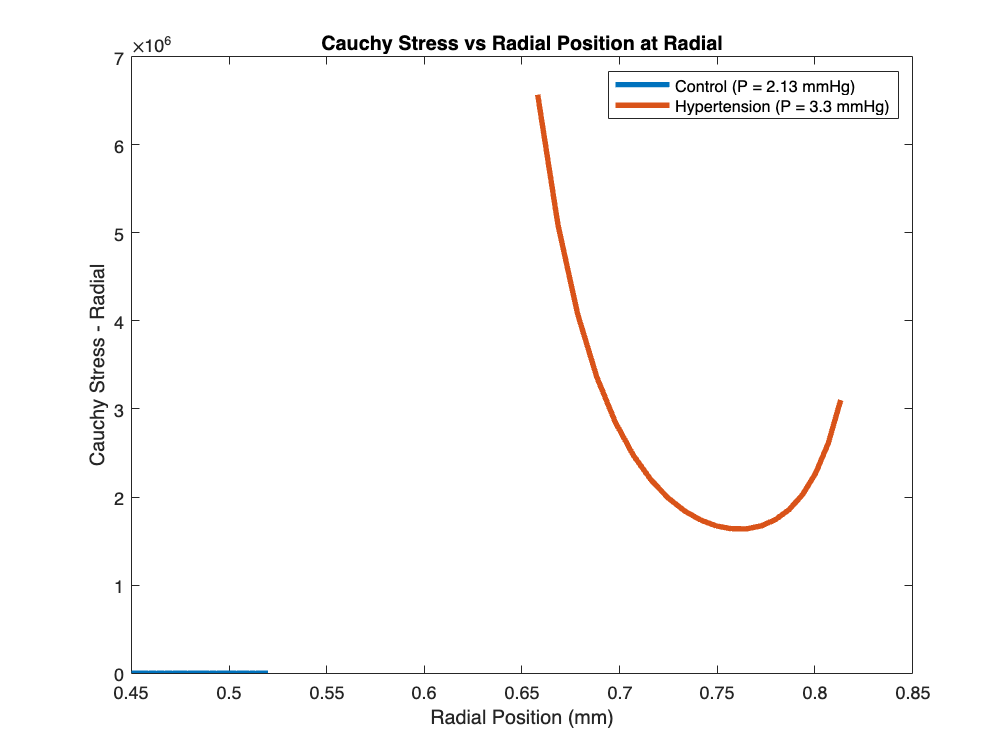

% Plot
figure()
plot(R_control, control_stress_rr,R_test,test_stress_rr, 'LineWidth',3)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Radial')
legend('Control (P = 2.13 mmHg)','Hypertension (P = 3.3 mmHg)')
title('Cauchy Stress vs Radial Position at Radial')

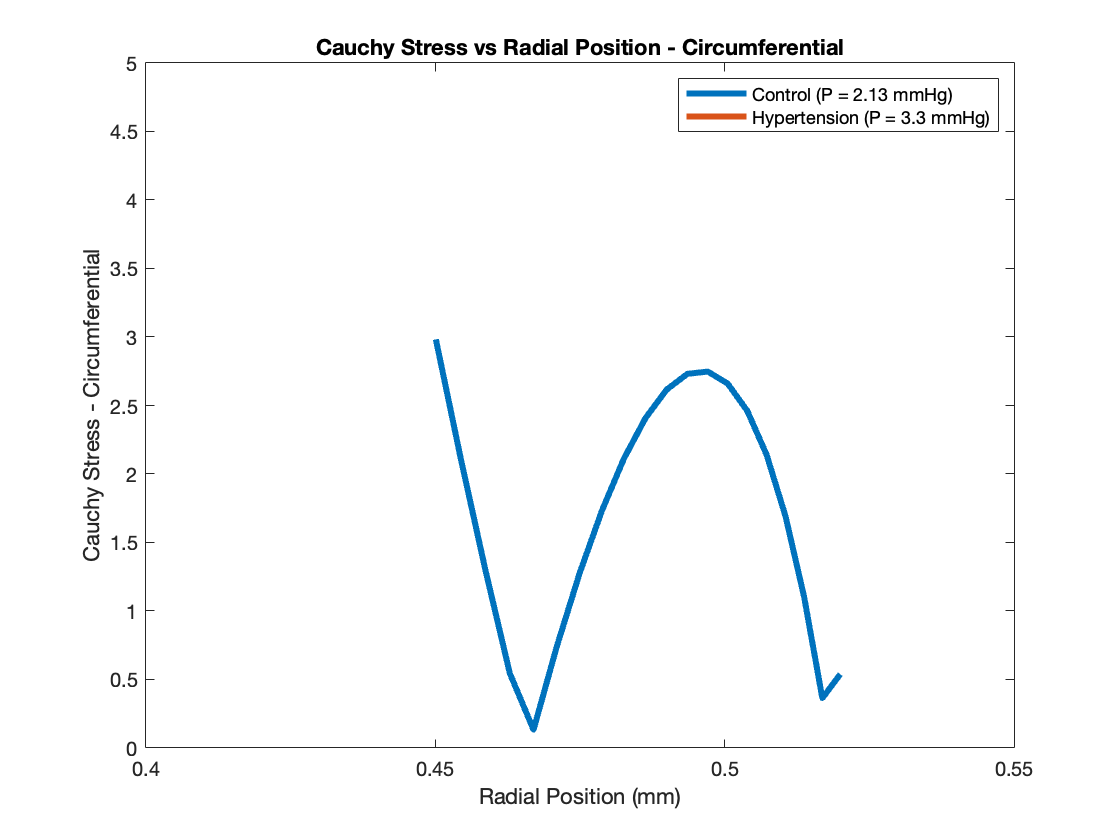


%xlim([0.4 0.55])
%ylim([-2.7 17.3])

figure()
plot(R_control, control_stress_theta,R_test,test_stress_theta, 'LineWidth',3)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Circumferential')
legend('Control (P = 2.13 mmHg)','Hypertension (P = 3.3 mmHg)')
title('Cauchy Stress vs Radial Position - Circumferential')

xlim([0.4 0.55])
ylim([0 5])

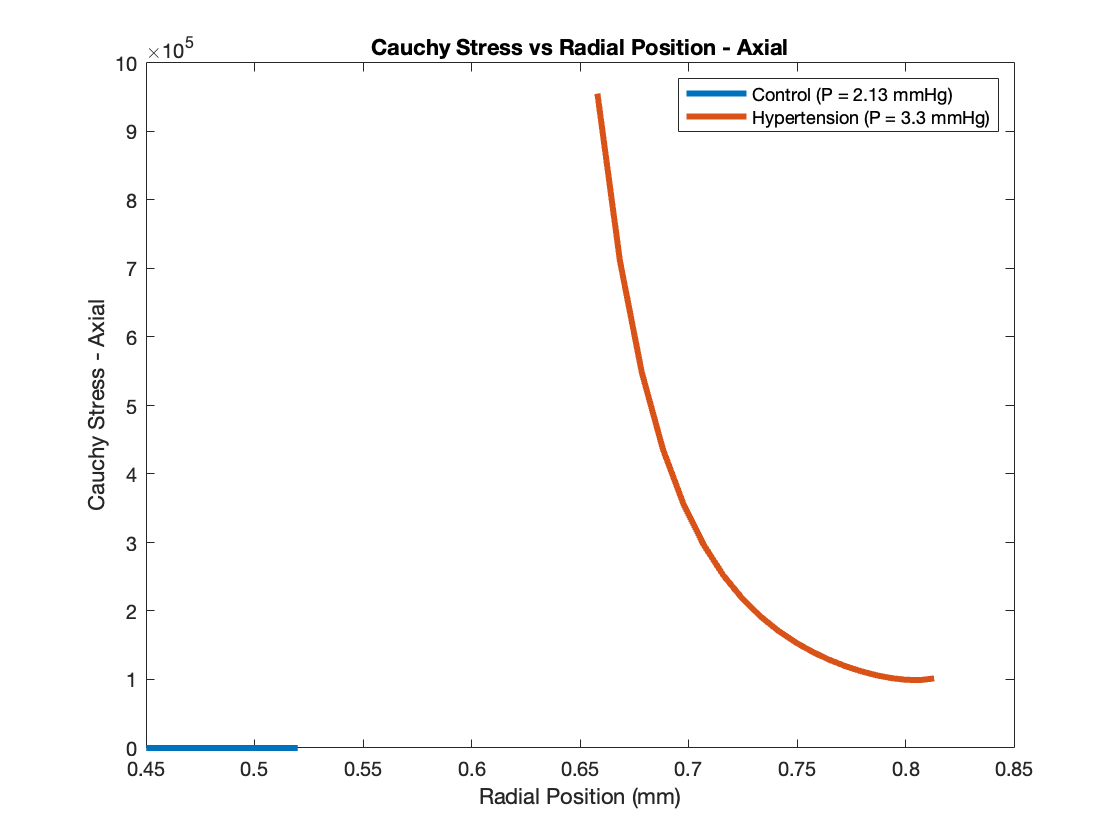


figure()
plot(R_control, control_stress_zz,R_test,test_stress_zz, 'LineWidth',3)
xlabel('Radial Position (mm)')
ylabel('Cauchy Stress - Axial')
legend('Control (P = 2.13 mmHg)','Hypertension (P = 3.3 mmHg)')
title('Cauchy Stress vs Radial Position - Axial')

%xlim([0.4 0.55])
%ylim([455 465])
